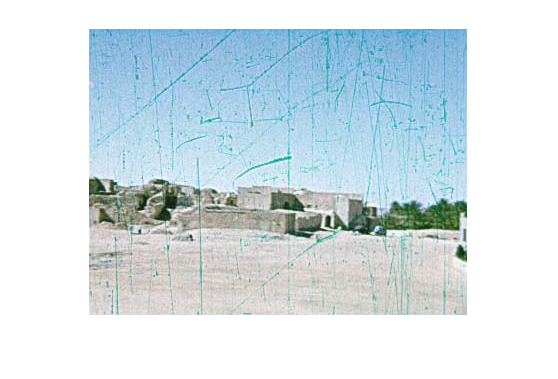

%Load and display original image
figure

img = imread('Important_files/film1_big.jpg');
[h,w,c] = size(img);

img_cropped = img(1:(h/5)-2,(w/3)+2:(2*w/3)-5,:);

imshow(img_cropped, []);

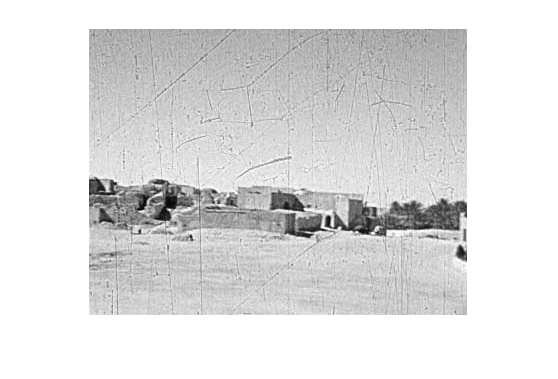


img_oc = img_cropped(:,:,2);

imshow(img_oc,[]);

%Highlighting scratches using high pass filter in fourier space

dft = fftshift(fft2(img_oc));

imshow(log(abs(dft)), []);

D0 = 1/8 * sqrt(2*128^2);
[rows,cols] = size(dft);
maxu = cols/2;
maxv = rows/2;
u = linspace(1, 2*maxu, 2*maxu) - maxu;
v = linspace(1, 2*maxv, 2*maxv) - maxv;
[uu,vv] = meshgrid(u,v);
filter = (sqrt(uu.^2 + vv.^2) <= D0);
%filter = (exp(-(uu.^2 + vv.^2)./(2*D0^2)));
imshow(filter, [])

filter_high_pass = 1 -  filter;

filtered_high_pass = filter_high_pass.*dft;

filtered_high_pass_spatial = real(ifft2(fftshift(filtered_high_pass)));

imshow(filtered_high_pass_spatial, []);

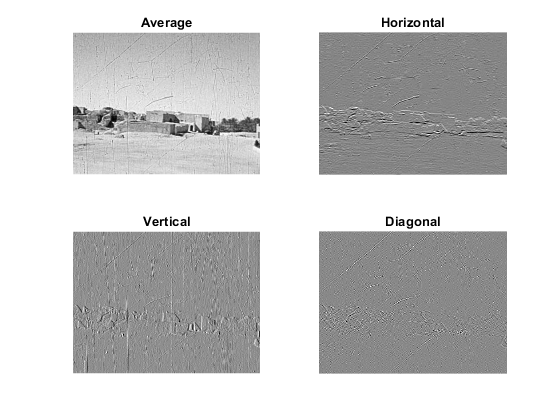

%Wavelet approach

[cA, cH, cV, cD] = dwt2(img_oc, 'haar');

figure
subplot(2,2,1)
imshow(cA, [])
title('Average')

subplot(2,2,2)
imshow(cH, [])
title('Horizontal')

subplot(2,2,3)
imshow(cV, [])
title('Vertical')

subplot(2,2,4)
imshow(cD, [])
title('Diagonal')


%We should compare different wavelets and level of analysis and show that
%we think this one is the best. (Only one level can be explained as the
%vertical, horizontal and diagonal details we want to detect are quite
%fine)

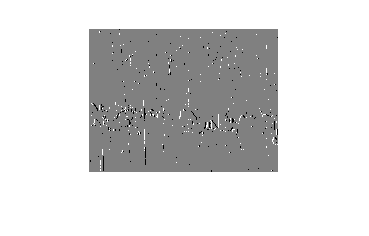

%Code for classifying pixel as scratch or no scratch

figure

threshold = 30;

classified = abs(cV);
classified(find(classified < threshold)) = 0;
classified(find(cV >= threshold)) = 1;
classified(find(cV <= -threshold)) = -1;

imshow(classified, []);

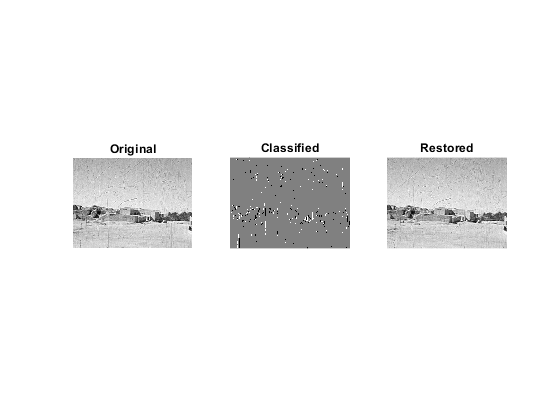

restored = img_oc;

[class_rows, class_cols] = size(classified);

for row = 2:(class_rows - 2)
    for col = 2:(class_cols - 2)
        classification = classified(row,col);
        if(classification == 1)
            restored(row*2 - 1, col*2) = img_oc(row*2 - 1, col*2 - 1);
            restored(row*2, col*2) = img_oc(row*2, col*2 - 1);
        elseif(classification == -1)
            restored(row*2 - 1, col*2 - 1) = img_oc(row*2 - 1, col*2);
            restored(row*2, col*2 - 1) = img_oc(row*2, col*2);
        end
        %if(classification ~= 0)
        %    restored(row*2 - 1, col*2) = uint8(mean(mean(img_oc(row*2 - 2 : row*2, col*2 - 1 : col*2 + 1)))); 
        %    restored(row*2, col*2) = uint8(mean(mean(img_oc(row*2 - 1 : row*2 + 1, col*2 - 1 : col*2 + 1))));
        %    restored(row*2 - 1, col*2 - 1) = uint8(mean(mean(img_oc(row*2 - 2 : row*2, col*2 - 2 : col*2))));
        %    restored(row*2, col*2 - 1) = uint8(mean(mean(img_oc(row*2 - 1 : row*2 + 1, col*2 - 2 : col*2))));
        %end
    end
end

figure
subplot(1,3,1)
imshow(img_oc, [])
title('Original')

subplot(1,3,2)
imshow(classified, [])
title('Classified')

subplot(1,3,3)
imshow(restored, [])
title('Restored')



%imshow(cV + cD, [])

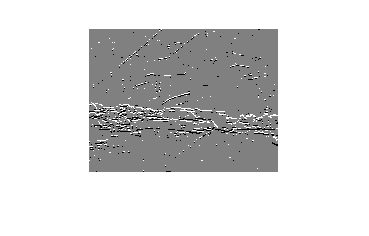

figure

threshold = 20;

classified = abs(cH);
classified(find(classified < threshold)) = 0;
classified(find(cH >= threshold)) = 1;
classified(find(cH <= -threshold)) = -1;

imshow(classified, []);

for row = 1:(class_rows - 1)
    for col = 1:(class_cols - 1)
        classification = classified(row,col);
        if(classification == 1)
            restored(row*2, col*2 - 1) = img_oc(row*2 - 1, col*2 - 1);
            restored(row*2, col*2) = img_oc(row*2 - 1, col*2);
        elseif(classification == -1)
            restored(row*2 - 1, col*2 - 1) = img_oc(row*2, col*2 - 1);
            restored(row*2 - 1, col*2) = img_oc(row*2, col*2);
        end
    end
end

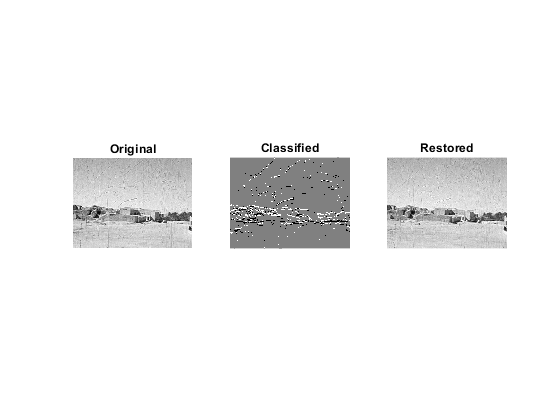

figure
subplot(1,3,1)
imshow(img_oc, [])
title('Original')

subplot(1,3,2)
imshow(classified, [])
title('Classified')

subplot(1,3,3)
imshow(restored, [])
title('Restored')

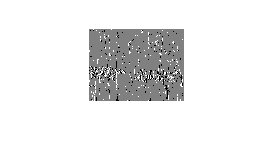

figure

[cA2, cH2, cV2, cD2] = dwt2(cA, 'haar');

threshold = 30;

classified2 = abs(cV2);
classified2(find(classified2 < threshold)) = 0;
classified2(find(cV2 >= threshold)) = 1;
classified2(find(cV2 <= -threshold)) = -1;

imshow(classified2, []);